# Cruise Control: PID

## Pure P control

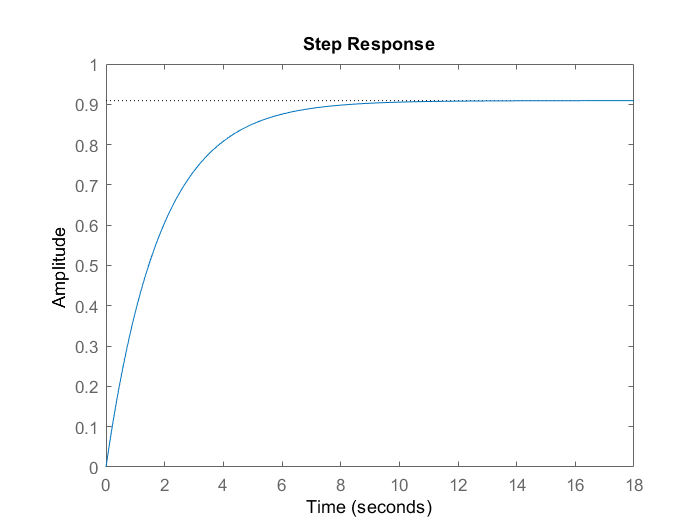

% plant model
m = 1000;
b = 50;
sys_tf = 1/(m*s + b);

% P controller
kp = 500;
C = pid(kp, 0, 0);

% simulation
sys = feedback(C*sys_tf, 1);
step(sys);

You can increase the proportional gain Kp to reduce the rise time and the steady-state error. Change the existing m-file so that  equals 5000 and it reaches to almost one, But a higher Kp will reach to the limitation of actuator which causes satuaration. **Actuator limitations** are very frequently encountered in practice in control systems engineering, and consequently, the required control action must always be considered when proposing a new controller. One solution is to use a smaller Kp but with integral control

## PI control

**Note**: When you adjust the integral gain Ki, we suggest you to start with a small value since a large Ki can de-stabilize the response. 

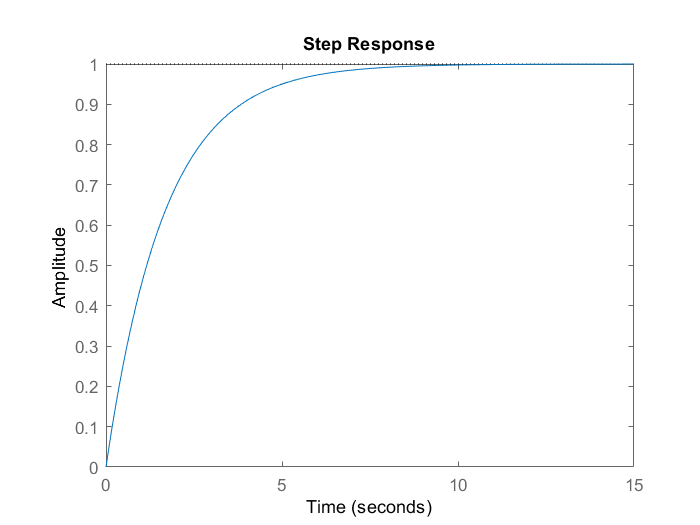

kp = 600;
ki = 30;
C_pi = pid(kp, ki, 0);

sys = feedback(C_pi * sys_tf, 1);
step(sys)

Now, it meets the requirements

**Suggestion:** Usually choosing appropriate gains requires a trial and error process. The best way to attack this tedious process is to adjust one variable at a time and observe how changing one variable influences the system output. 